Часть 1. Исследование статистических характеристик ДПТ НВ

Механическая характеристика

% close all;
% U = [-U_nom: 0.25*U_nom: U_nom];
% M = [-2*M_nom: 0.01:2* M_nom];
% figure
% for i=1:length(U)
%     w = U(i)/psi - (R_phase/psi^2).*M;
%     hold all
%     plot(M, w, 'LineWidth', 2);
% end
% grid on
% title('$\omega(M)$','Interpreter', 'latex', 'FontSize', 16);
% ylabel('$\omega$, rad/s', 'Interpreter', 'latex', 'FontSize', 15);
% xlabel('M, Hm', 'Interpreter', 'latex', 'FontSize', 15);
% legend("U=$-U_{nom}$", "U=$-0.75U_{nom}$","U=$-0.5U_{nom}$","U=$-0.25U_{nom}$","U=$0$","U=$0.25U_{nom}$","U=$0.5U_{nom}$","U=$0.75U_{nom}$","U=$U_{nom}$", 'Interpreter', 'latex', 'FontSize', 15);
% hold off;

Регулировочная характеристика

% U = [-U_nom: 0.01: U_nom];
% M = [-M_nom: 0.25*M_nom:M_nom];
% figure
% for i=1:length(M)
%     w = U/psi - (R_phase/psi^2).*M(i);
%     hold all
%     plot(U, w, 'LineWidth', 2);
% end
% grid on
% title('$\omega(U)$','Interpreter', 'latex', 'FontSize', 16);
% ylabel('$\omega$, rad/s', 'Interpreter', 'latex', 'FontSize', 15);
% xlabel('U, V', 'Interpreter', 'latex', 'FontSize', 15);
% legend("M=$-M_{nom}$", "M=$-0.75M_{nom}$","M=$-0.5M_{nom}$","M=$-0.25M_{nom}$","M=$0$","M=$0.25M_{nom}$","M=$0.5M_{nom}$","M=$0.75M_{nom}$","M=$M_{nom}$", 'Interpreter', 'latex', 'FontSize', 15);
% hold off;

Электромеханическая постоянная

Время необходимое для разгона двигателя до угловой скорости холостого хода

% J_motor*R_phase/psi^2;

Часть 2. Исследование динамических характеристик ДПТ НВ

Построение графиков

% plot(out.w.Time,out.w.Data, 'LineWidth', 2);
% hold on;
% title('$\omega(t)$','Interpreter', 'latex', 'FontSize', 16);
% ylabel('$\omega$, rad/s', 'Interpreter', 'latex', 'FontSize', 15);
% xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% hold off;
% 
% plot(out.M.Time,out.M.Data, 'LineWidth', 2);
% hold on;
% title('$M(t)$','Interpreter', 'latex', 'FontSize', 16);
% ylabel('M, Hm', 'Interpreter', 'latex', 'FontSize', 15);
% xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% hold off;
% 
% plot(out.T.Time,out.T.Data, 'LineWidth', 2);
% hold on;
% title('$T(t)$','Interpreter', 'latex', 'FontSize', 16);
% ylabel('T, H', 'Interpreter', 'latex', 'FontSize', 15);
% xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% hold off;
% 
% plot(out.M.Data,out.w.Data, 'LineWidth', 2);
% hold on;
% title('$\omega(M)$','Interpreter', 'latex', 'FontSize', 16);
% ylabel('$\omega$, rad/s', 'Interpreter', 'latex', 'FontSize', 15);
% xlabel('M, Hm', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% hold off;

Часть 3

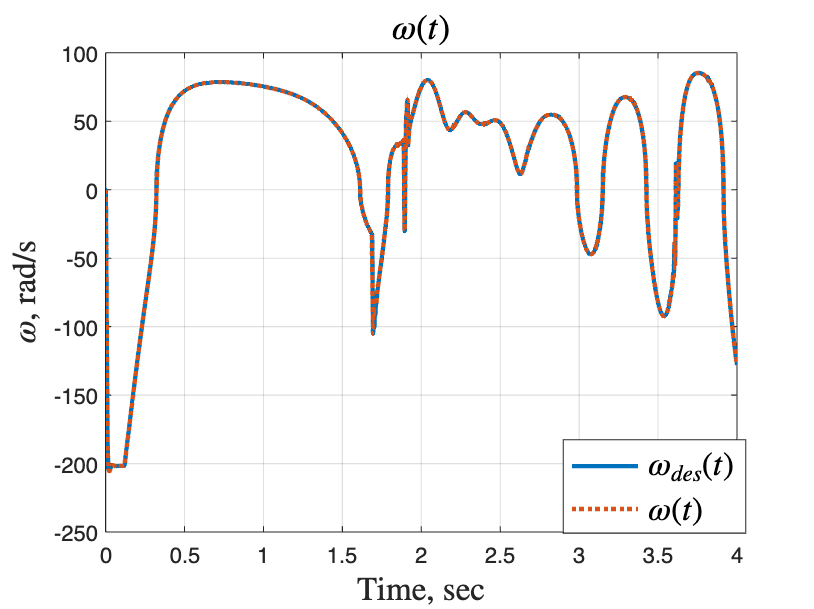

plot(out.wd3.Time,out.wd3.Data, 'LineWidth', 2);
hold on;
plot(out.w3.Time,out.w3.Data, 'LineWidth', 2, 'LineStyle',':');
title('$\omega(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('$\omega$, rad/s', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\omega_{des}(t)$", "$\omega(t)$", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;